# Dual-Polarity GRAPPA (DPG) reconstruction

Rex Fung, July 10th, 2024

## Load in params

Sequence design params

setGREparams; setEPIparams;

% Params defined at scanner
% What you set toppe CV 8 to when running the scan
Nloops_acs = 10;
Nloops = 10;

Nframes_acs = Nloops_acs*NframesPerLoop*2;
Nframes = Nloops*NframesPerLoop;

% Filenames
datdir = '/mnt/storage/rexfung/20240711epi/';
fn_cal = strcat(datdir,'cal.h5');
fn_acs = strcat(datdir,'acs.h5');
fn_loop = strcat(datdir,'loop.h5');
fn_adc = sprintf('adc/adc%d.mod',Nx);

% Options
showEPIphaseDiff = true;

## Load in raw data

Read using Matteo's scripts

ksp_cal_raw = read_archive(fn_cal);
ksp_acs_raw = read_archive(fn_acs);
ksp_raw = read_archive(fn_loop);
[Nfid, Ncoils] = size(ksp_raw,2,5);

% Print max real and imag parts to check for reasonable magnitude
fprintf('Max real part of cal data: %d\n', max(real(ksp_cal_raw(:))))
fprintf('Max imag part of cal data: %d\n', max(imag(ksp_cal_raw(:))))
fprintf('Max real part of acs data: %d\n', max(real(ksp_acs_raw(:))))
fprintf('Max imag part of acs data: %d\n', max(imag(ksp_acs_raw(:))))
fprintf('Max real part of loop data: %d\n', max(real(ksp_raw(:))))
fprintf('Max imag part of loop data: %d\n', max(imag(ksp_raw(:))))

## Preprocessing

Permute and reshape to to [Nfid, Ncoils, ...]

ksp_cal = permute(squeeze(ksp_cal_raw),[2,4,1,3]);
ksp_acs = permute(squeeze(ksp_acs_raw),[2,4,1,3]);
ksp_rs = permute(squeeze(ksp_raw),[2,4,1,3]);

% discard leading blank space
ksp_cal = ksp_cal(:,:,(size(ksp_cal,3) + 1):end);
ksp_acs = ksp_acs(:,:,(size(ksp_acs,3) + 1):end);
ksp_rs = ksp_rs(:,:,(size(ksp_rs,3) + 1):end);

% discard trailing blank space
ksp_cal = ksp_cal(:,:,1:Ny*Nz);
ksp_acs = ksp_acs(:,:,1:Ny*Nz*Nframes_acs);
ksp_rs = ksp_rs(:,:,1:Ny*Nz*Nframes);

% Reshape and permute EPI calibration data (a single frame w/o blips)
% [Nfid, Ny/Nsegments, Nsegments, Nz, Ncoils]
ksp_cal = reshape(ksp_cal,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz);
ksp_cal = permute(ksp_cal,[1 3 4 5 2]);

% Reshape and permute DPG ACS data
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes_acs, Ncoils]
ksp_acs = reshape(ksp_acs,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes_acs);
ksp_acs = permute(ksp_acs,[1 3 4 5 6 2]);

% Reshape and permute EPI loop data
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes, Ncoils]
ksp_rs = reshape(ksp_rs,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes);
ksp_rs = permute(ksp_rs,[1 3 4 5 6 2]);

## Estimate k-space offset and linear phase correction values

Estimate k-space center offset due to gradient delay

cal_data = reshape(abs(ksp_cal),Nfid,Ny/Nsegments,Nsegments*Nz*Ncoils);
cal_data(:,2:2:end,:) = flip(cal_data(:,2:2:end,:),1);
[M, I] = max(cal_data,[],1);
delay = 2*mean(I,'all') - Nfid;
fprintf('Estimated offset from center of k-space (samples): %f\n', delay);

% retrieve sample locations from .mod file with adc info
[rf,gx,gy,gz,desc,paramsint16,pramsfloat,hdr] = toppe.readmod(fn_adc);
[kxo, kxe] = toppe.utils.getk(sysGE, fn_adc, Nfid, delay);

% Extract even number of lines (in case ETL is odd)
ETL_even = size(ksp_cal,2) - mod(size(ksp_cal,2),2);
oephase_data = ksp_cal(:,1:ETL_even,:,:,:);

% EPI ghost correction phase offset values
oephase_data = hmriutils.epi.rampsampepi2cart(oephase_data, kxo, kxe, Nx, fov(1)*100, 'nufft');
oephase_data = ifftshift(ifft(fftshift(reshape(oephase_data,Nx,ETL_even,Nsegments*Nz*Ncoils)),Nx,1));
[a, th] = hmriutils.epi.getoephase(oephase_data,showEPIphaseDiff);
fprintf('Constant phase offset (radians): %f\n', a(1));
fprintf('Linear term (radians/fov): %f\n', a(2));

## Sort apart the ACS data into + and - polarities

% Average odd and even polarity frames
ksp_acs_plus = squeeze(mean(ksp_acs(:,:,:,:,1:2:end,:),5));
ksp_acs_minus = squeeze(mean(ksp_acs(:,:,:,:,2:2:end,:),5));

% Swap every other line
tmp = ksp_acs_minus(:,2:2:end,:,:,:);
ksp_acs_minus(:,2:2:end,:,:,:) = ksp_acs_plus(:,2:2:end,:,:,:);
ksp_acs_plus(:,2:2:end,:,:,:) = tmp;
clear tmp;

% Sort segments/shots into proper locations
ksp_acs_plus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
ksp_acs_minus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
for seg = 1:Nsegments
    ksp_acs_plus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_plus(:,:,seg,:,:,:));
    ksp_acs_minus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_minus(:,:,seg,:,:,:));
end

## Visualize

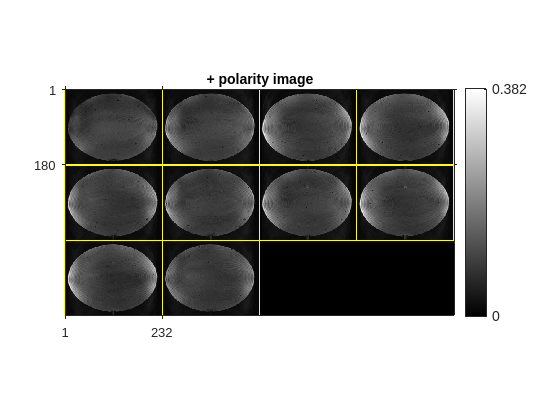

% Look at the corresponding RSOS images
figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_plus_sorted)).^2,4)),'cbar')
title('+ polarity image');

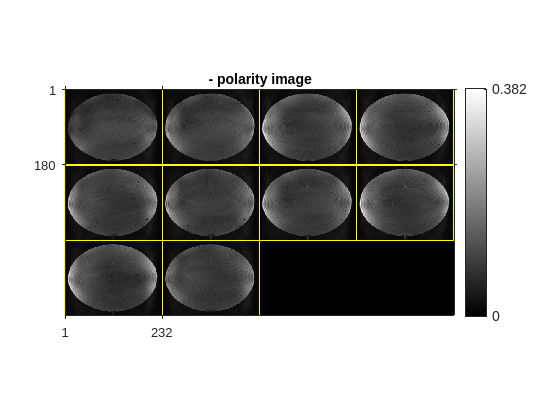

figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_plus_sorted)).^2,4)),'cbar')
title('- polarity image');

## Phase correct ACS data

## Compute DPG kernel weights from ACS data

## Reconstruct k-space

## Enforce low-rankness

## Display